close all; clc; clear;

A1 = 1; A2 = 1;
f1 = 1; f2 = 8;
T1 = 1/f1; T2 = 1/f2;
phi1 = pi/6; phi2 = 3;

#### Frequenza di campionamento

fc = 256;

#### Tempo di campionamento

Tc = 1/fc;

#### Frequenza fondamentale

T = double(lcm(sym(T1),sym(T2)));

#### Orizzonte temporale

t = [-T/2 : Tc : T/2 - Tc + 0.56];

#### Segnale

x = A1*sin(2*pi*f1*t+phi1)+A2*cos(2*pi*f2*t+phi2);

N = length(x);

### Dispersione Spettrale

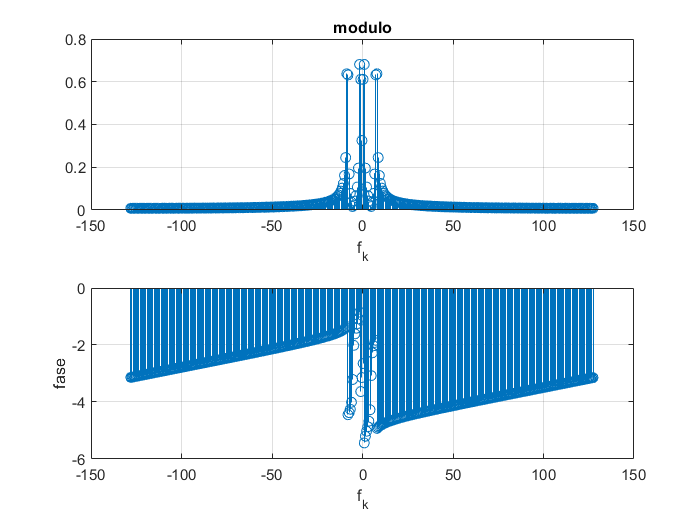

X = fft(x);

Xs = fftshift(X);

Xreal = real(Xs);
j = find( abs(Xreal) <= 10e-10 );
Xreal(j) = 0;

Ximaginary = imag(Xs);
j = find( abs(Ximaginary) <= 10e-10 );
Ximaginary(j) = 0;

bin = fc/N;
fk = [-fc/2 : bin : (fc/2) - bin];

figure(1);
subplot(2,1,1),stem(fk,2*abs(complex(Xreal,Ximaginary))/N);
xlabel('f_k'); title('modulo'); grid;
subplot(2,1,2),stem(fk,(unwrap(angle(complex(Xreal,Ximaginary))))) ; 
xlabel('f_k'); ylabel('fase'); grid;

### Funzione di Hann

w1 = hanning(length(x))';
y1 = x.*w1;

### Funzione di Bartlett

w2 = bartlett(length(x))';
y2 = x.*w2;

### Modulo e Fase dopo aver applicato la funzione di Hann e la funzione di Bartlett

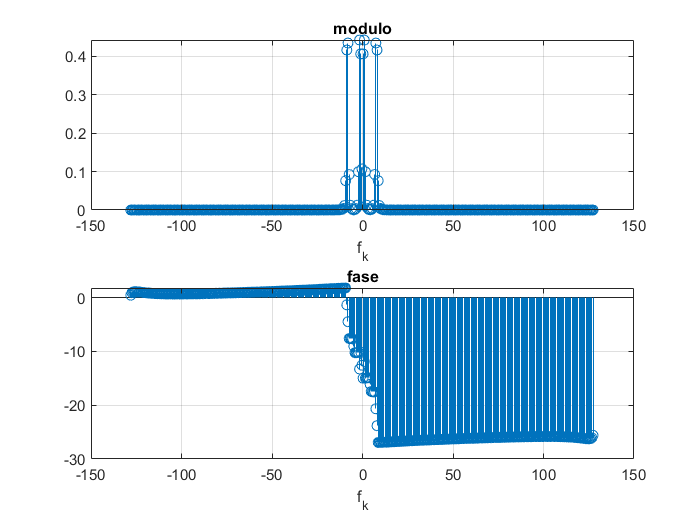

X1 = fftshift(fft(y1));
X2 = fftshift(fft(y2)); 


Xr1 = real(X1); j = find(abs(Xr1)<=10e-10); Xr1(j) = 0;
Xi1 = imag(X1);j = find(abs(Xi1)<=10e-10); Xi1(j) = 0;

Xr2 = real(X2); j = find(abs(Xr2)<=10e-10); Xr2(j) = 0;
Xi2 = imag(X2);j = find(abs(Xi2)<=10e-10); Xi2(j) = 0;


figure(2);
subplot(2,1,1),stem(fk,2*abs(complex(Xr1,Xi1))/N); 
xlabel("f_k") ; title('modulo'); grid;
subplot(2,1,2),stem(fk,(unwrap(angle(complex(Xr1,Xi1))))); 
xlabel("f_k"); title('fase'); grid;

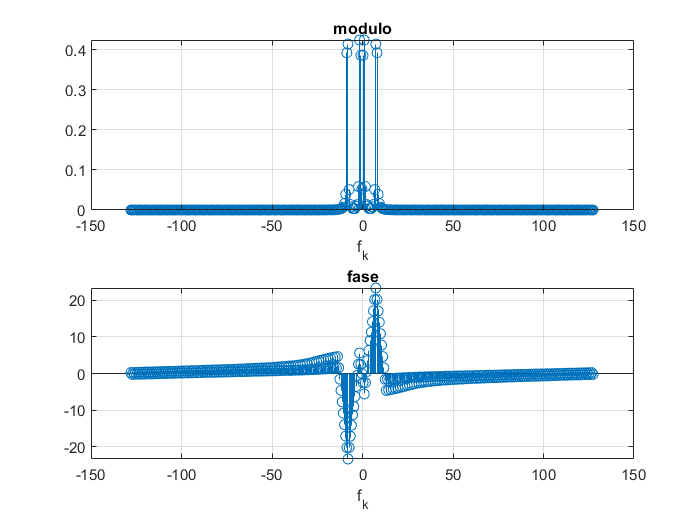


figure(3);
subplot(2,1,1),stem(fk,2*abs(complex(Xr2,Xi2))/N); 
xlabel("f_k"); title('modulo'); grid;
subplot(2,1,2),stem(fk,(unwrap(angle(complex(Xr2,Xi2))))); 
xlabel("f_k"); title('fase'); grid;

### Finestratura

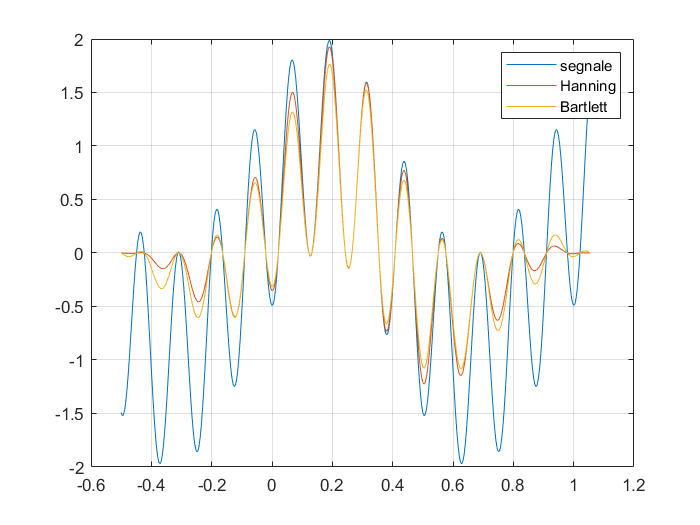

figure(4); 
plot(t,x); 
hold on; 
plot(t,y1);
hold on;
plot(t,y2);
grid;
legend('segnale','Hanning','Bartlett');